# RoadRunner - Simulinkのcosimulation

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;
setenv("NO_PROXY", "localhost");

## RoadRunnerをMATLABから起動する

### ※RoadRunnerからSimulinkへアクセスするため、必ずMATLABからRoadRunnerを起動すること

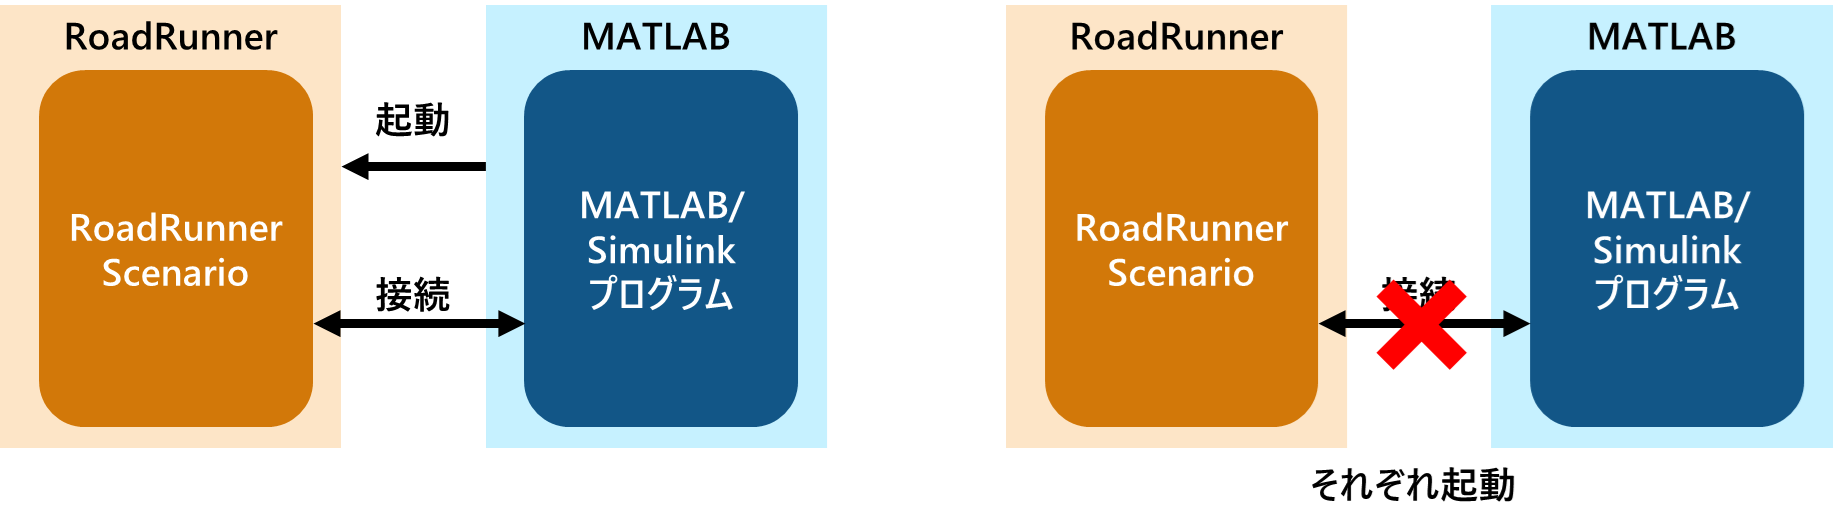

% R2024a以前のversionで実施する場合は、次のコマンドで例題を開き、そちらを実行ください
% openExample('autonomous_control/AuthorRoadRunnerActorUsingSimulinkExample')

rrApp = roadrunner();
rrProjectPath = rrApp.status.Project.Filename;
copyfile("RRfiles/TrajectoryCutInWithVariables.rrscenario",fullfile(rrProjectPath,"Scenarios/"));
copyfile("RRfiles/MySimulinkBehavior.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));

% シナリオを起動　シーンはシナリオと紐づいているため、自動でシーンも開く
rrApp.openScenario("TrajectoryCutInWithVariables");

% RoadRunnerとSimulinkの実行ステップサイズを揃える
simStepSize = 0.1;
rrSim = rrApp.createSimulation();
rrSim.set("StepSize", simStepSize);

% RoadRunnerの情報をSimulinkで取得するため、Busオブジェクトを定義
% To support Reader and Writer blocks, some bus objects must be loaded
loadRoadRunnerBusObject();

% 車両の位置変更定数
gainArg = [
    1 0 0 0.5;
    0 1 0 0.1;
    0 0 1 0;
    0 0 0 1];

% Simulinkのモデルを開く
model_name = 'SimulinkVehicle.slx';
open_system(model_name);

## RoadRunnerのアクターにBehaviorファイルを追加

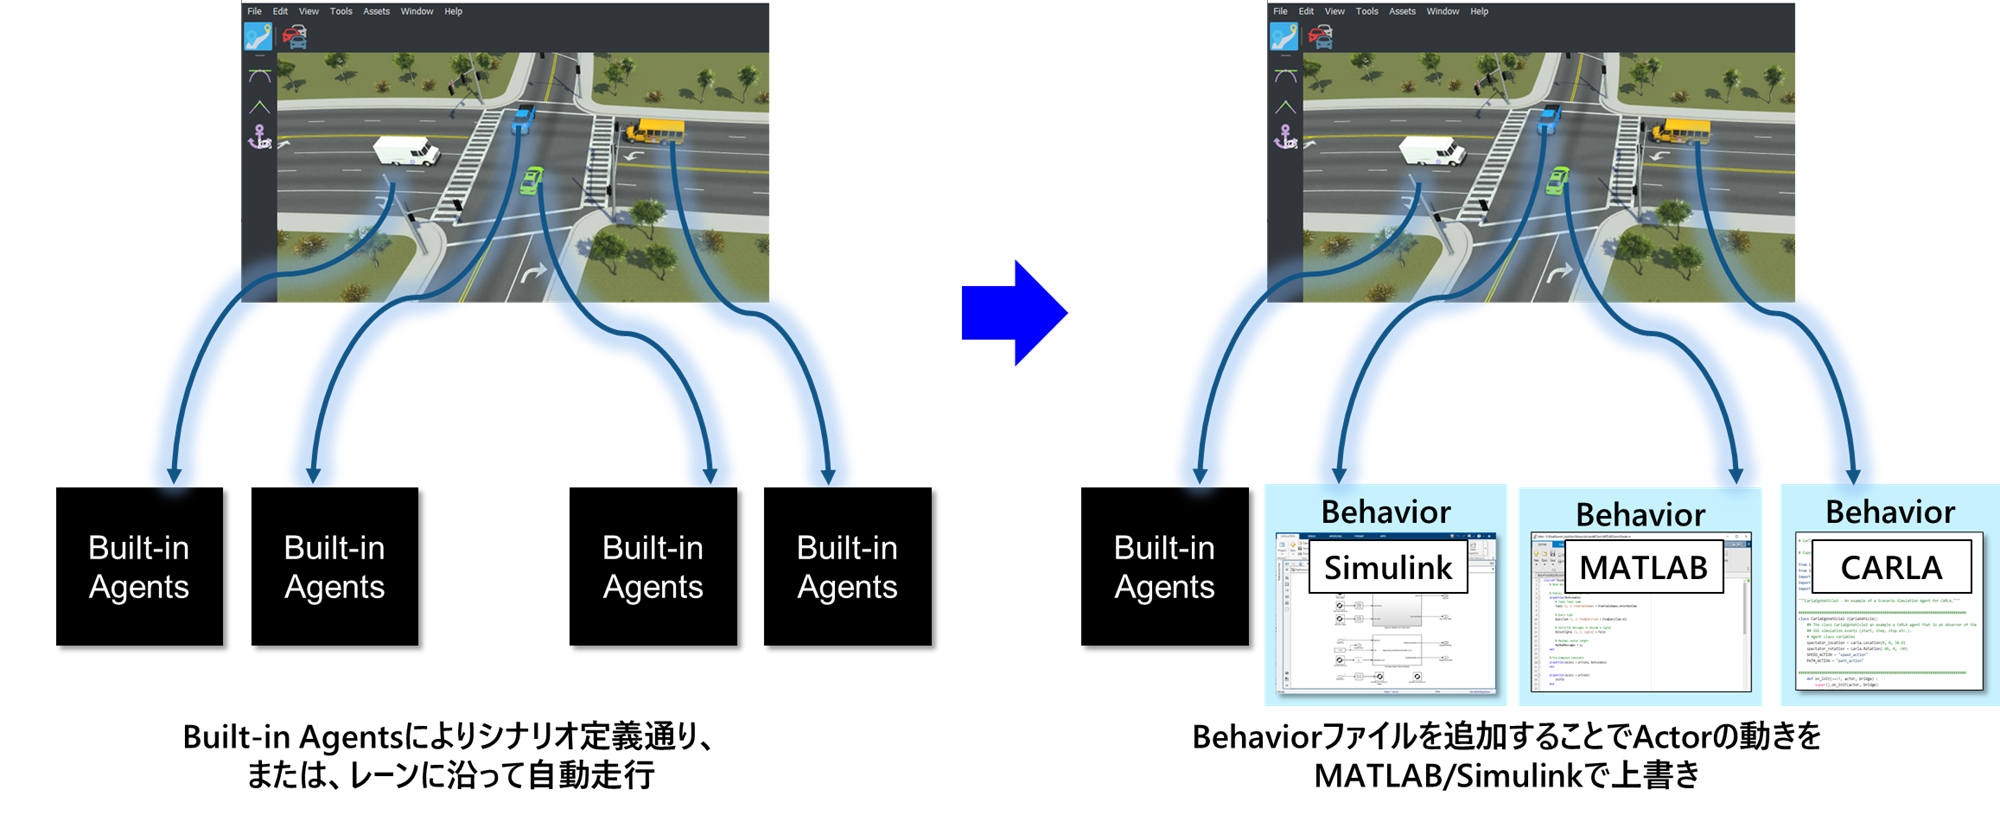

### Behaviorファイルをアクターに設定すし、Simulinkと連携する手順

1．RoadRunnerのLibarary BrowserにてBehaviorファイルを作成する　（SCENAIRIO EDITINGでないと作成できないため、注意！）

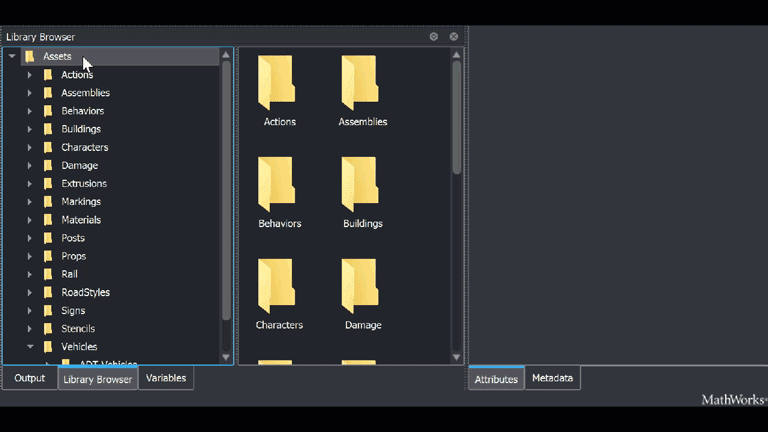

2．AttributesパネルにてPlatformをMATLAB/Simulinkに設定し、Simulinkファイル名を記述する。

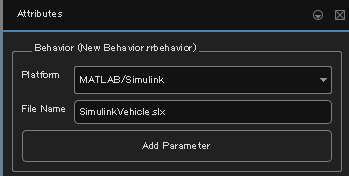

3．アクターをクリックし、AttributesパネルにてBehaviorをドラッグ&ドロップする

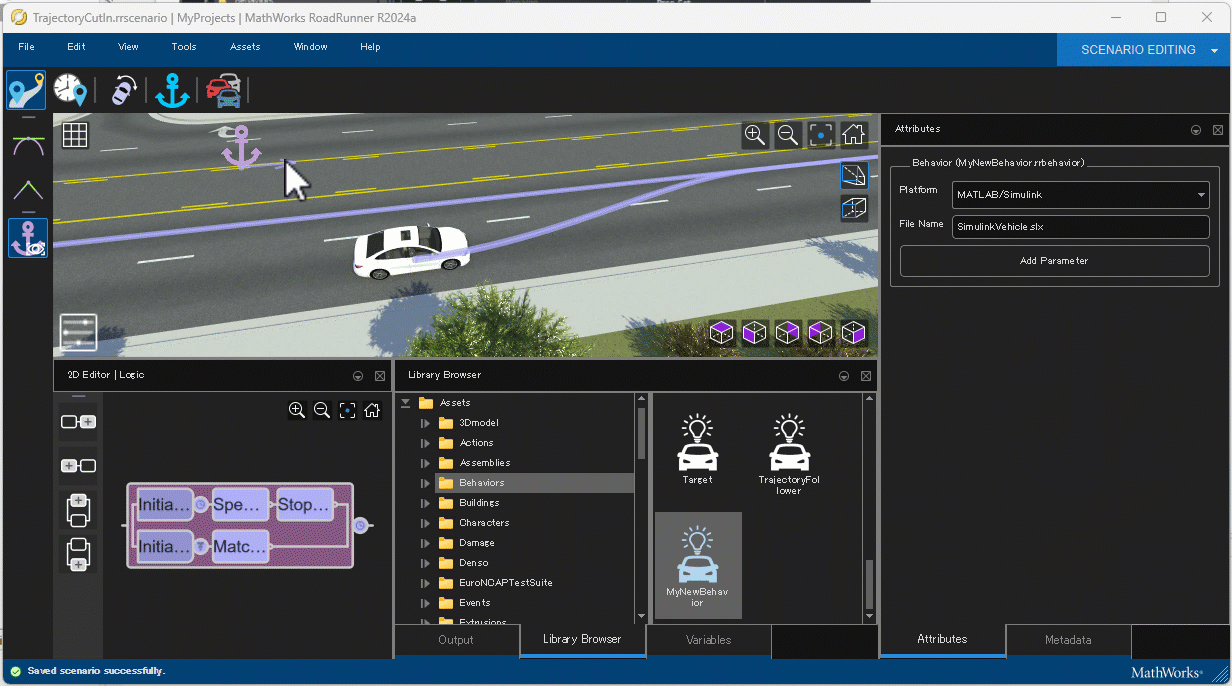

## MATLABからのBehaviorの設定

rrApp.setScenarioVariable("EgoBehavior", "<PROJECT>/Assets/Behaviors/MySimulinkBehavior.rrbehavior");

## RoadRunnerを実行する

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

## SimulinkVehicle.slxの動作

SimulinkVehicleは下記動作を毎ステップ実施

1．現在の姿勢をRoadRunnerのアクターより取得（[RoadRunner Scenario Reader](https://jp.mathworks.com/help/driving/ref/roadrunnerscenarioreader.html)ブロック）し、

2．現在姿勢にgainArgを加算（＝x位置を0.5m加算）

3．2の計算結果をRoadRunnerアクターに設定（[RoadRunner Scenario Writer](https://jp.mathworks.com/help/driving/ref/roadrunnerscenariowriter.html)ブロック）

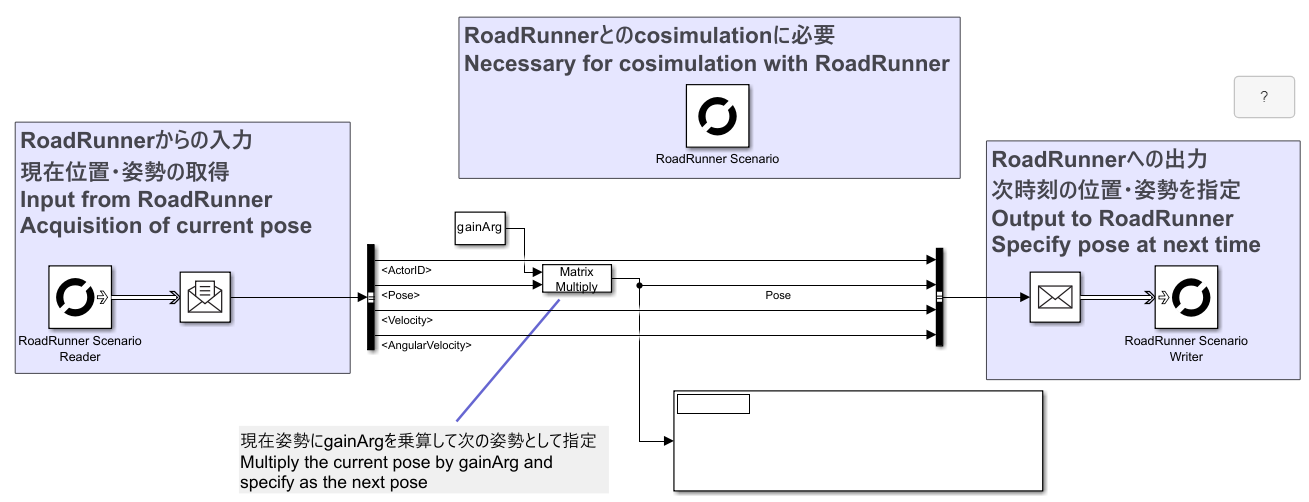

#### [RoadRunner Scenario Reader](https://jp.mathworks.com/help/driving/ref/roadrunnerscenarioreader.html)ブロック、[RoadRunner Scenario Writer](https://jp.mathworks.com/help/driving/ref/roadrunnerscenariowriter.html)ブロックはアクターの姿勢の他にイベントやシナリオで定義したパスなどのアクション取得が可能 （詳細はリンク先のドキュメンテーションを参照）

## 参考：RoadRunner Scenarioのアクターの位置・姿勢

RoadRunner Scenarioでは4×4の同次座標系の剛体変換行列で現在位置と姿勢を表現

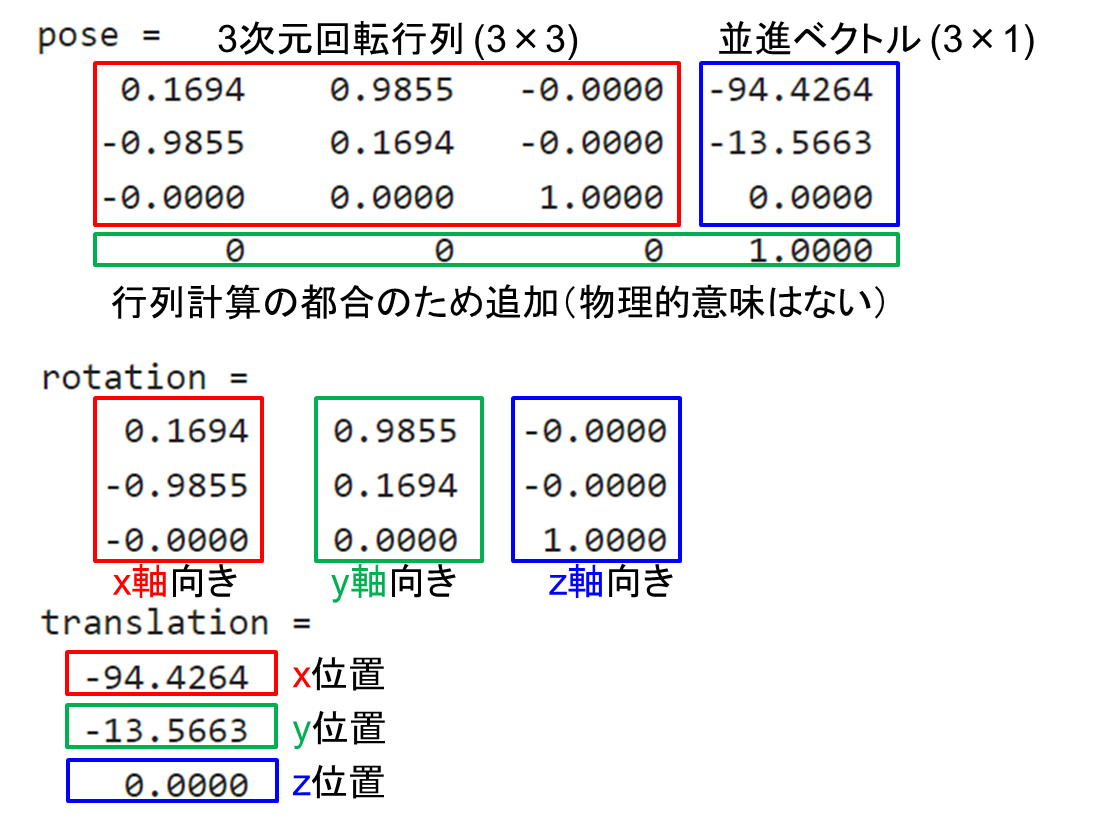

例）x位置を1m進ませるとき

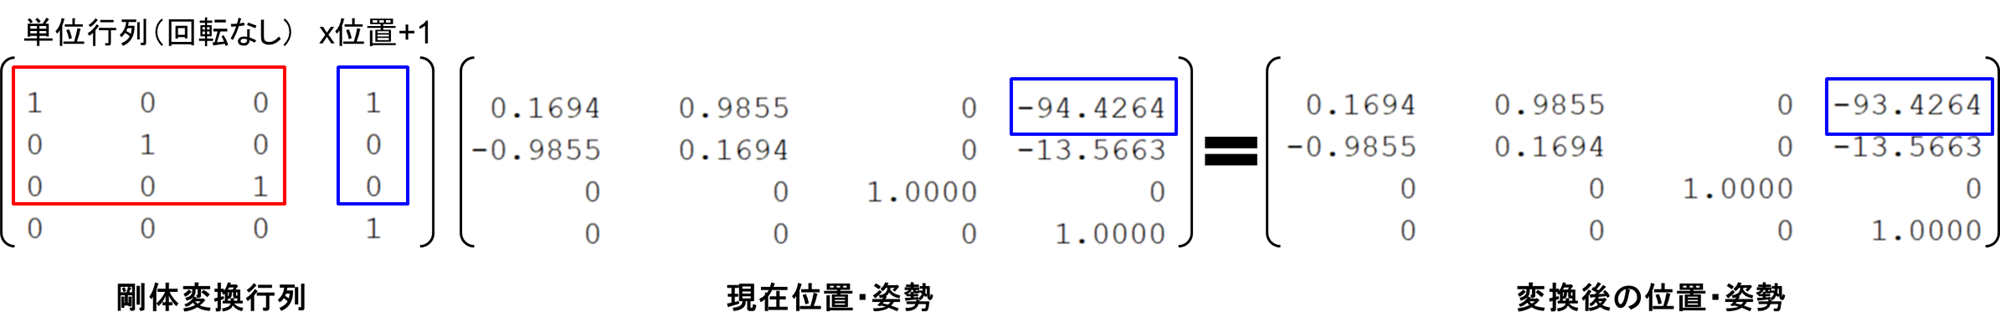

詳細は[こちらのドキュメンテーション](https://jp.mathworks.com/help/driving/ug/what-is-roadrunner-pose-matrix.html)を参照

## 発展：gainArgの値を変更し、車両の動きの違いを確認しよう

% x, y, zの移動量を変更するとき
x_offset = 1;
y_offset = 0.1;
z_offset = 0.5;
gainArg(1,4) = x_offset;
gainArg(2,4) = y_offset;
gainArg(3,4) = z_offset;

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

## 参考：Simulinkの実行ステップサイズ設定

Simulinkの1ステップごとの時間は下記で設定可能

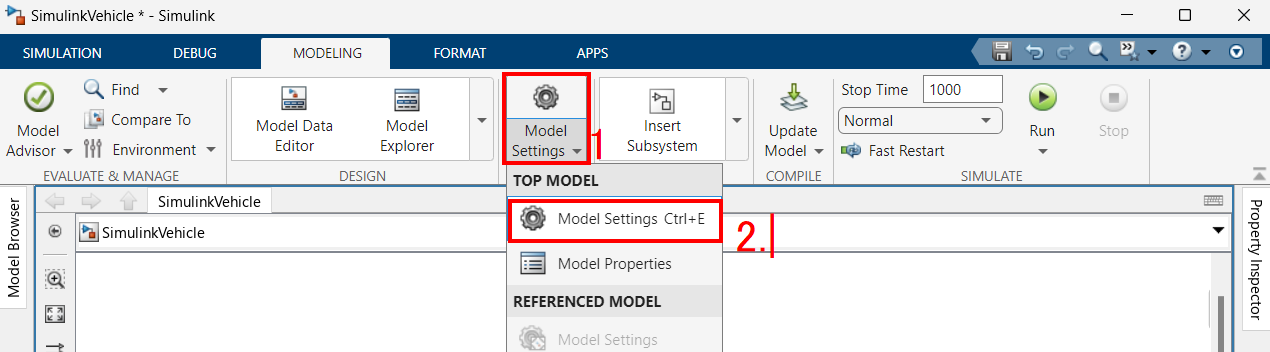

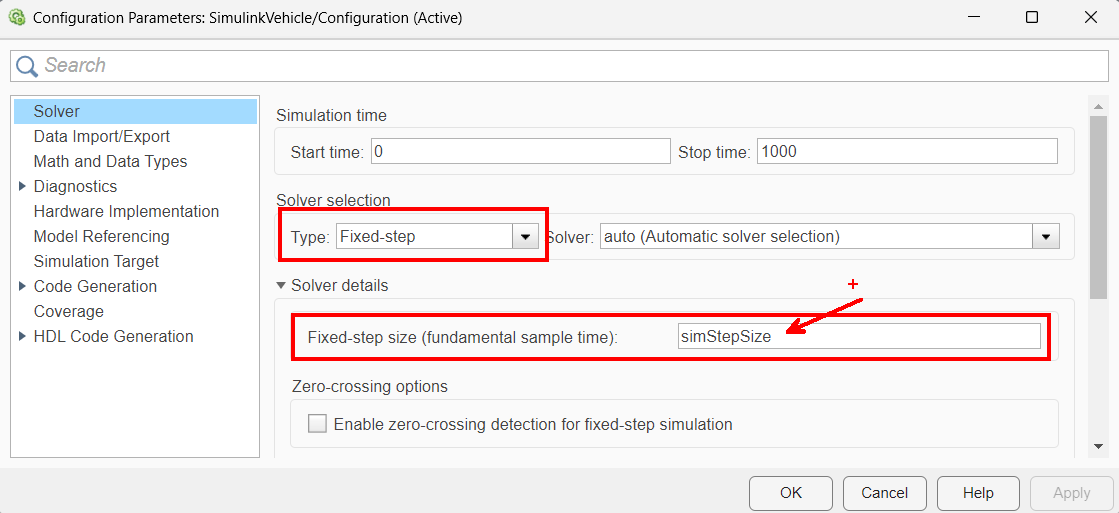

## 参考：RoadRunnerの実行ステップサイズ設定

RoadRunnerの1ステップごとの時間は下記で設定可能